dataFolder = '/GEE_30m';
imgDir = fullfile(pwd, dataFolder, 'images');
imds = imageDatastore(imgDir)

imds =   ImageDatastore with properties:

                       Files: {
                              'D:\Do an\GEE_30m\images\s1_flooded_20201010.tif';
                              'D:\Do an\GEE_30m\images\s1_flooded_20201017.tif';
                              'D:\Do an\GEE_30m\images\s1_flooded_20201023.tif'
                               ... and 2 more
                              }
                     Folders: {
                              'D:\Do an\GEE_30m\images'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


labelIDs = [0 1];
pixelLabelIDs = {0 1};
classes = ["no_label", "flood"];

labelDir = fullfile(pwd, dataFolder, 'labels');
pxds = pixelLabelDatastore(labelDir, classes, pixelLabelIDs);

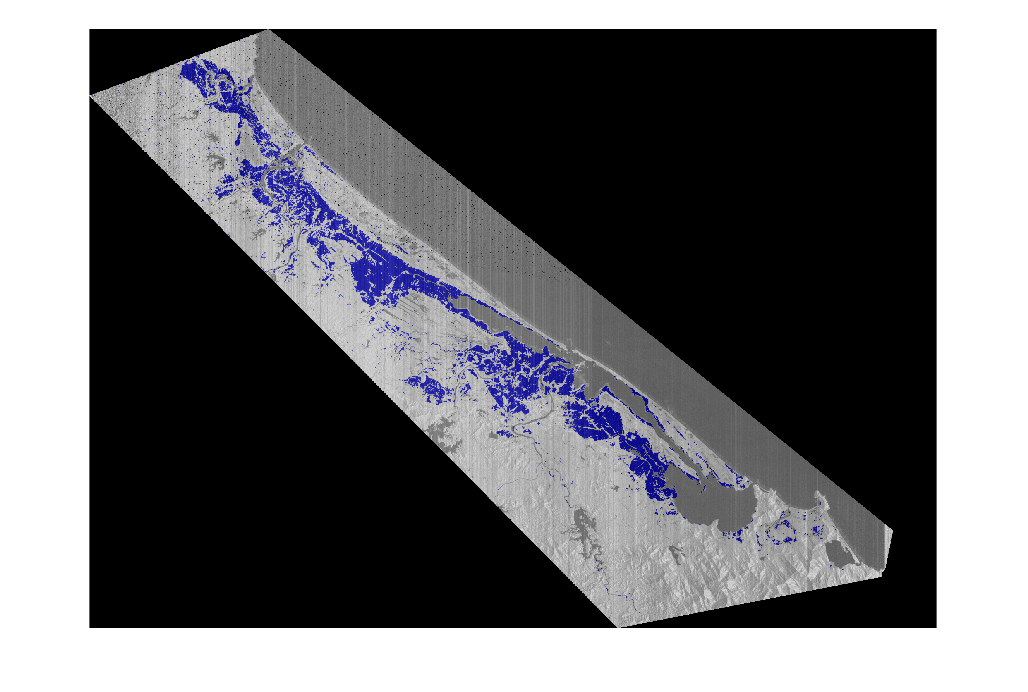

i = readimage(imds, 1);
c = readimage(pxds, 1);
i1 = normalize(i, 'range', [0 1]);
c1 = double(c);
b = labeloverlay(i1,c1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(b);

tbl = countEachLabel(pxds)

tbl = 2×3 table
        Name        PixelCount    ImagePixelCount
    ____________    __________    _______________

    {'no_label'}    8.8934e+07      9.1342e+07   
    {'flood'   }     2.408e+06      9.1342e+07   


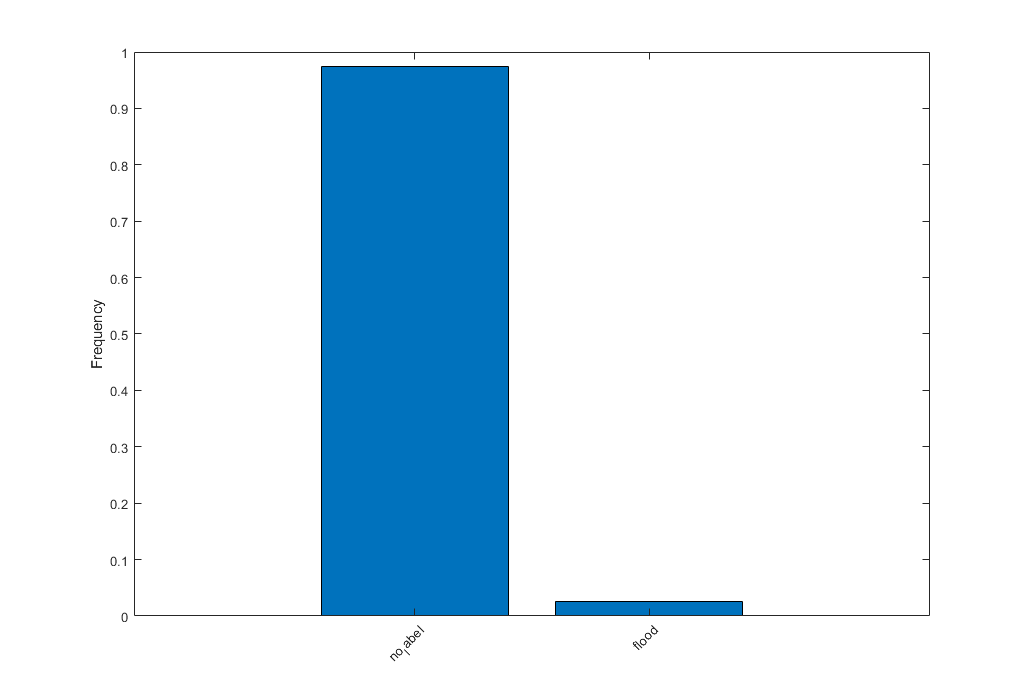

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     0.5135
   18.9663


inputTileSize = [256, 256, 1];
dsTrain = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), 0.01, 1000, ...
    "PatchesPerImage", 16000, ...
    "DispatchInBackground", true);
inputBatch = preview(dsTrain);
disp(inputBatch)

       InputImage       ResponsePixelLabelImage
    ________________    _______________________

    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 
    {256×256 double}     {256×256 categorical} 



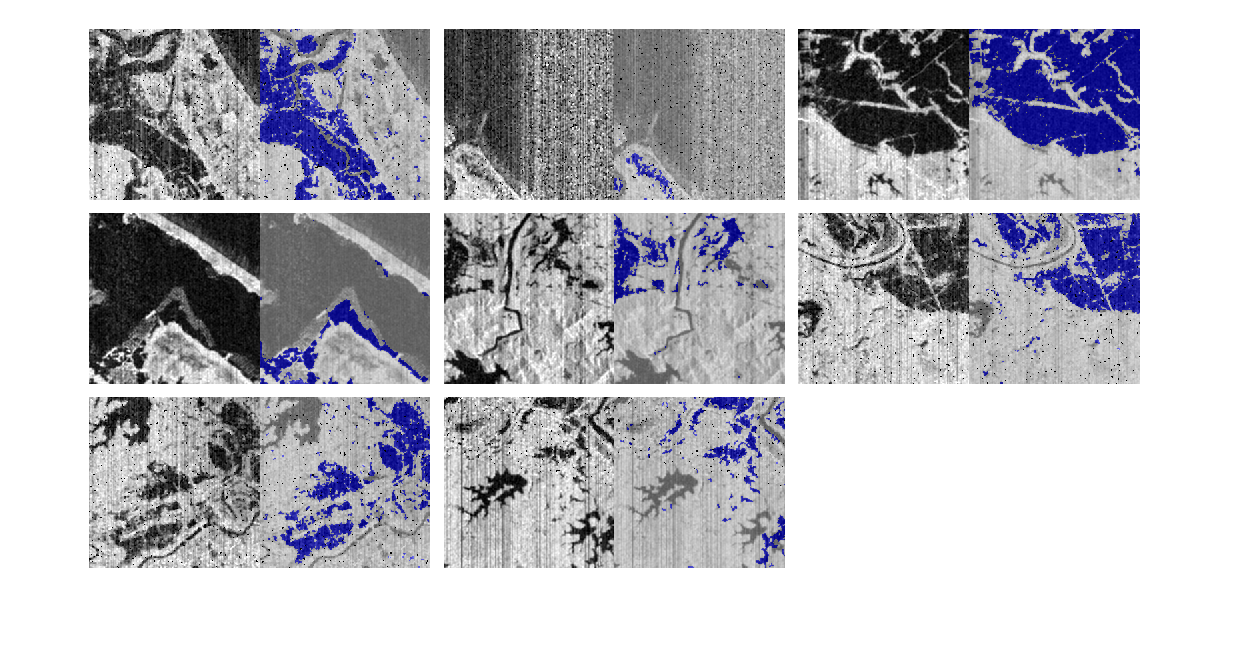

showImageWithLabel(inputBatch)

pxLayer = dicePixelClassificationLayer('Name','dice-Pixel-Classification-Layer','Classes',tbl.Name);
lgraph = createUnet(inputTileSize, numel(classes), pxLayer);
disp(lgraph.Layers)

  58×1 Layer array with layers:

     1   'ImageInputLayer'                        Image Input                       480×256×1 images with 'zerocenter' normalization
     2   'Encoder-Section-1-Conv-1'               Convolution                       64 3×3×1 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'Encoder-Section-1-ReLU-1'               ReLU                              ReLU
     4   'Encoder-Section-1-Conv-2'               Convolution                       64 3×3×64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'Encoder-Section-1-ReLU-2'               ReLU                              ReLU
     6   'Encoder-Section-1-MaxPool'              Max Pooling                       2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'Encoder-Section-2-Conv-1'               Convolution                       128 3×3×64 convolutions with stride [1  1] and pad

initialLearningRate = 0.05;
maxEpochs = 50;
minibatchSize = 16;
l2reg = 0.0001;

options = trainingOptions('sgdm',...
    'InitialLearnRate',initialLearningRate,...
    'Momentum',0.9,...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs,...
    'MiniBatchSize',minibatchSize,...
    'LearnRateSchedule','piecewise',...    
    'Shuffle','every-epoch',...
    'GradientThresholdMethod','l2norm',...
    'GradientThreshold',0.05,...
    'Plots','training-progress',...
    'VerboseFrequency',20,...
    "ExecutionEnvironment","cpu",...
    "CheckpointPath", strcat(pwd, dataFolder, '/checkpoint'));

doTraining = true;
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    [net,info] = trainNetwork(dsTrain,lgraph,options);
    save(['savedUnet-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net','options');
end

Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:06:49 |       40.11% |       0.6855 |          0.0500 |


|========================================================================================|
